# Bayesian SVAR identified with sign restrictions

The purpose of the code is to estimate a Bayesian SVAR with 2 different priors: flat and minnesota. Then the variance-covariance matrix is identified using sign restrictions.

The code is very general, by changing the parameters in the section "Import the data and set main parameters", it can be readapted to datasets with any number of variables. Moreover it can be used to identify any type of shocks with sign restriction methodology by changing the variable "set.restrictions". Since we use the flat and minnesota priors, we don't have to set any prior parameter.

I created 2 main functions: 1. "minnesota_prior": very general function to create the minnesota prior; 2. "sign_restrictions": it draws a matrix exploiting the QR decomposition and it checks if it satisfies or not the sign restriction.

In this case the code is used to identify 3 shocks: demand, energy and supply. The dataset is quarterly, based on U.S. data, which starts in 1989:I and ends in 2023:IV. It includes n = 3 variables: (i) the logarithm of real Personal Consumption Expenditure (C); (ii) the logarithm of the chain-type price index of Personal Consumption Expenditure excluding Food and Energy (coreP); and (iii) the logarithm of the chain-type price index of Personal Consumption Expenditure in Energy Goods and Services (energyP).

clear;
clc;
rng("default")
addpath("functions")

#### 1) Import the data and set main parameters

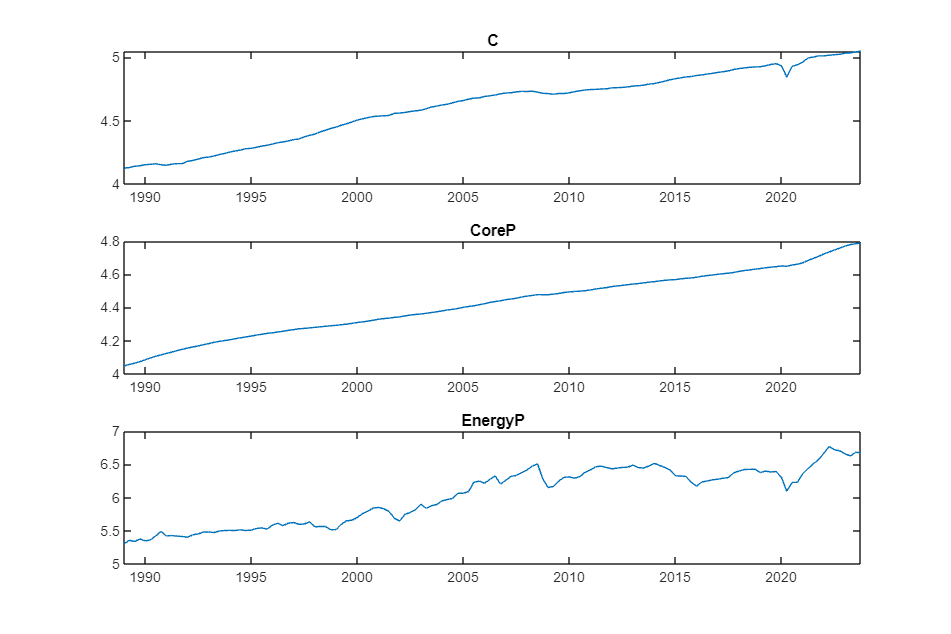

%Import and arrange the data
raw_data = readtable("data.xlsx");
set.dates = table2array(raw_data(:, 1));
set.data = table2array(raw_data(:, 2:end));

% Manual parameters
set.irf_horizon = 20; %IRFs horizon
set.T = 124; %lenght used to estimate the sample
set.growth_rate = 4; %Since the data is quarterly, we are considering annual change
set.p = 4; %number of lags
set.select_shock = 1; %Recontruct the last part of the sample using only the selected shock (point 6)
set.restrictions = [1 1 1; 1 -1 0; 1 1 -1]; % -1: negative, 1: positive, 0: neutral, notice that the matrix has to be set.n x set.n
set.variable_names = {"C", "CoreP", "EnergyP"}; %it has to be the same as the order on x
set.shock_names = {"Demand shock", "Supply shock", "Energy shock"}; %it has to be the same as the order on x

% Default parameters
set.lambda = 0.2;
set.n = size(set.data, 2); %number of variables
set.k = set.n*set.p + 1; %number of regressors per variable + constant
set.mc_sim = 50000;

clear raw_data

figure('Position',[200 100 900 600]);
for i=1:set.n
    subplot(set.n, 1, i);
    plot(set.dates, set.data(:, i));
    title(set.variable_names(i))
end

#### 2) Estimate the VAR(p) with OLS

$y_t = c + B_1 y_{t-1} + ... + B_p y_{t-p} + u_{t}$  with  $u_{t} \sim N(0, S)$ 

where 

$x = [1 \; y_{t-1} \; y_{t-2} \; ... \; y_{t-p}]$, $y = y_{t}$ and $\hat{B}_{ols} = (x'x)^{-1}x'y$

$X = I_{n} \otimes  x$, $Y = vec(y)$ and $\hat{b}_{ols} = (X'X)^{-1}X'Y$


$$\hat{S}_{ols} = (y - xB)'(y - xB)$$


Notice that we assign all the variables related to the ols estimates to the struct "ols". 


set.x = [];
% Construct the x variable with p lags
for i=1:set.p
    j = set.p - i + 1;
    set.x = [set.data(i:end-j, :) set.x];
end
set.x = [ones(size(set.x,1), 1) set.x];
set.y = set.data(set.p+1:end,:);

% Now we select the obs up to set.T, since we don't use the entire sample
% for the estimation, and we construct the matrices used for the estimation
x = set.x(1:set.T-set.p, :);
y = set.y(1:set.T-set.p, :);
X = kron(eye(set.n), x);
Y = y(:);

clear i j

%% OLS estimates
ols.B = inv(x'*x)*x'*y;
ols.b = inv(X'*X)*X'*Y;
ols.S = (y - x*ols.B)'*(y - x*ols.B);

#### 3) Posterior distribution of parameters under flat prior

Under flat prior, the posterior distribution of parameters is:


$$S_{post}|Y \tilde{} IW(S_{ols}, T-p-n-k-1) $$



$$b_{post}|S_{post},Y \tilde{} N(b_{ols}, S_{post} \otimes (x'x)^{-1})) $$


Notice that we assign all the variables related to the flat prior to the struct "flat". 

flat.b_post = zeros(set.mc_sim, set.k*set.n, 1);
flat.S_post = zeros(set.mc_sim, set.n, set.n);

% Posterior distribution
for i=1:set.mc_sim
    flat.S_post(i, :, :) = iwishrnd(ols.S, set.T-set.p-set.n-set.k-1);
    flat.b_post(i, :, :) = mvnrnd(ols.b, kron(squeeze(flat.S_post(i, :, :)), inv(x'*x)));
end

flat.S_post_median = median(flat.S_post); 
flat.S_post_median = squeeze(flat.S_post_median(1,:,:));

flat.b_post_median = median(flat.b_post); 
flat.b_post_median = squeeze(flat.b_post_median(1,:,:));

clear i
display(reshape(flat.b_post_median, [], set.n));

   -0.0257    0.0210    0.1473
    1.1027    0.0388    1.9575
   -0.1164    1.4334    4.8487
   -0.0131    0.0014    1.1149
    0.0639   -0.0642   -2.6208
   -0.0430   -0.3970   -2.4525
    0.0131   -0.0037   -0.3939
    0.0405    0.0296    1.2949
   -0.0878    0.1636   -7.2809
   -0.0019    0.0004    0.3168
   -0.2199    0.0009   -0.4244
    0.2824   -0.2103    4.6860
   -0.0062    0.0020   -0.0946



display(flat.S_post_median);

    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0022



#### 4) Identification with sign restrictions under flat prior

The structural VAR has the following form:

$y_t = c + B_1 y_{t-1} + ... + B_4 y_{t-4} + \Gamma \epsilon_{t}$ where $\epsilon_{t} \sim N(0, I_{n})$ and  $\Gamma \Gamma = S
$

We identify the matrix $\Gamma
$ with sign restrictions, specified as follow:


$$\Gamma = \pmatrix{+\;+\;+\cr +\;-\;\pm\cr+\;+\;-}$$


% Pre-allocation of variables
flat.b_post = zeros(set.mc_sim, set.k*set.n, 1); % Posterior draws of beta
flat.S_post = zeros(set.mc_sim, set.n, set.n); % Posterior draws of sigma
flat.Gamma = zeros(set.mc_sim, set.n, set.n); %Matrix with identified shocks
flat.index_sign = []; %Index of matrices satisfying the sign restriction

% Posterior distribution, notice that I created the function sign
% restrictions, which gives you back the gamma draw, and it says if it
% satisfies the sign restriction given in input or not.
for i=1:set.mc_sim
    flat.S_post(i, :, :) = iwishrnd(ols.S, set.T-set.p-set.n-set.k-1);
    flat.b_post(i, :, :) = mvnrnd(ols.b, kron(squeeze(flat.S_post(i, :, :)), ...
        inv(x'*x)));
    % Check if the matrix satisfy the sign restriction, in case, store the
    % index of the matrix.
    [satisfied, flat.Gamma(i, :, :)] = ...
        sign_restrictions(squeeze(flat.S_post(i, :, :)), set.restrictions);
    if satisfied == 1
        flat.index_sign = [flat.index_sign i];
    end
end
flat.b_post_sign = flat.b_post(flat.index_sign, :, :);
flat.Gamma_sign = flat.Gamma(flat.index_sign, :, :);
clear Lambda H Q R satisfied i

Check that the decomposition is done well:

disp(squeeze(flat.Gamma(10, :, :))*squeeze(flat.Gamma(10, :, :))' ...
    - squeeze(flat.S_post(10,:,:)));

   1.0e-20 *

         0   -0.0741   -0.6776
   -0.0741    0.0635    0.3388
   -0.6776    0.3388         0



Now put the VAR(4) in companion form VAR(1), and we plot the impulse responses.

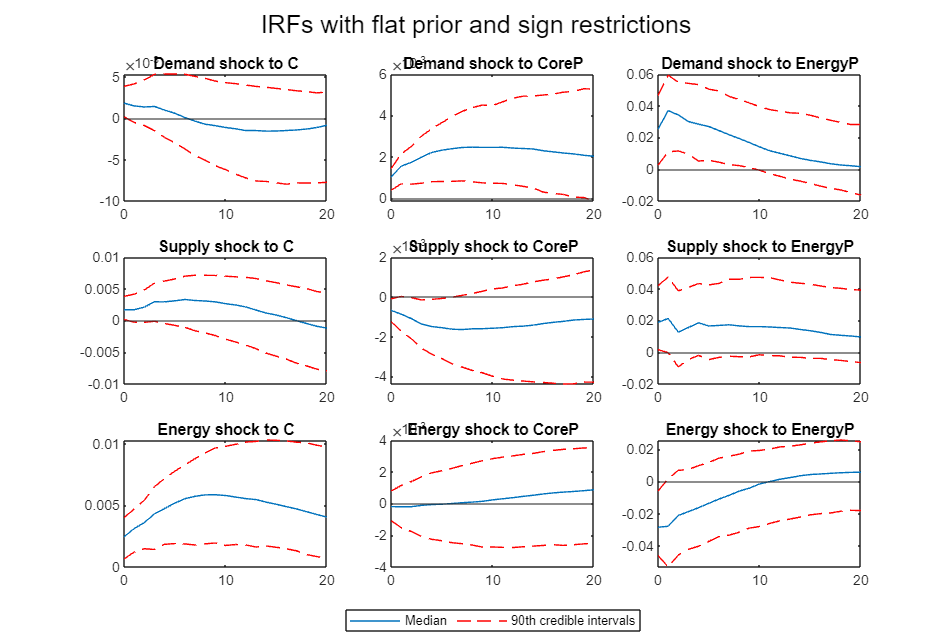

% Put VAR(4) in companion form and compute IRFs
flat.IRF = zeros(size(flat.index_sign, 2), set.n*set.n, set.irf_horizon+1);
for i=1:size(flat.index_sign, 2)
    % Reshape the parameter at every iteration
    B_post_draw = reshape(flat.b_post_sign(i,:,:), [], set.n);
    Gamma_draw = squeeze(flat.Gamma_sign(i, :, :));
    % Put B in companion form, select the betas without the intercept
    B_post_draw = [B_post_draw(2:end, :)'; eye(set.n*(set.p-1)) ...
        zeros(set.n*(set.p-1), set.n)];
    Gamma_draw = [Gamma_draw zeros(set.n, set.n*(set.p-1)); ...
        zeros(set.n*(set.p-1), set.n) zeros(set.n*(set.p-1), set.n*(set.p-1))];
    % Let's generate the IRFs for the selected horizon
    for h=0:set.irf_horizon
        %Use companion form to generate the shocks
        shocks = (B_post_draw^h)*Gamma_draw; 
        shocks = shocks(1:set.n, 1:set.n);
        %shock1: 1:set.n, shock2: set.n+1:2*set.n, ...
        flat.IRF(i, :, h+1) = shocks(:); 
    end
end

clear B_post_draw Gamma_draw i shocks h j

%Plot IRFs
figure('Position',[200 100 900 600]);
j=1;
for i=1:(set.n*set.n)
    subplot(set.n, set.n, i);
    plot(0:set.irf_horizon, prctile(squeeze(flat.IRF(:, i, :)), 50)', ...
        0:set.irf_horizon, prctile(squeeze(flat.IRF(:, i, :)), 5)', "--r", ...
        0:set.irf_horizon, prctile(squeeze(flat.IRF(:, i, :)), 95)', "--r");
    yline(0);
    title(sprintf("%s to %s", set.shock_names{j}, ...
        set.variable_names{i - set.n*(j-1)}))
    if rem(i, set.n) == 0; j = j+1; end
end
leg = legend("Median", "90th credible intervals", 'Location','southoutside', ...
    'orientation','horizontal');
leg.Position(1) = 0.4;
leg.Position(2) = 0.01;
sgtitle("IRFs with flat prior and sign restrictions")

#### 5) Identification with sign restriction under Minnesota prior

In this case the beta prior is not flat anymore, but it is specified as follow:


$$b|S \tilde{} N(b_{prior}, S \otimes \Omega_{prior} )$$


where $b_{prior}$ and $\Omega_{prior}$ are constructed in the traditional minnesota way (function "minnesota_prior").

While the prior on S is flat. The posterior distributions of parameters are:


$$b_{location} = (x'x + \Omega^{-1}_{prior})^{-1}(x'y + \Omega^{-1}_{prior}b_{prior})$$



$$S_{location} = (y - xb_{location})'(y - xb_{location}) + (b_{location} - b_{prior})'\Omega^{-1}(b_{location} - b_{prior})$$



$$S_{post}|Y \tilde{} IW(S_{location}, T-p-n-1) $$
 


$$b_{post}|S_{post},Y \tilde{} N(vec(b_{location}), S_{post} \otimes ((x'x) + \Omega_{prior}^{-1})^{-1})) $$


The the identification is done as in the previous section, the only difference are the resulting posterior

distributions of parameters. Notice that all the variables related to Minnesota prior are stored into 

the struc "minnesota".

minnesota.b_post = zeros(set.mc_sim, set.k*set.n, 1); % Posterior draws of beta
minnesota.S_post = zeros(set.mc_sim, set.n, set.n); % Posterior draws of sigma
minnesota.Gamma = zeros(set.mc_sim, set.n, set.n); %Matrix with identified shocks
minnesota.index_sign = []; %Index of matrices satisfying the sign restriction

%Compute the Minnesota prior, I created this function which is very general
% and it gives you back the beta and omega of the minnesota prior.
[minnesota.b_prior, minnesota.omega_prior] = ...
    minnesota_prior(y, x, set.n, set.k, set.T, set.p, set.lambda);

% Posterior locations of the Normal(location, scale) and IW(location, scale)
b_location = inv(x'*x + inv(minnesota.omega_prior))*...
    (x'*y + inv(minnesota.omega_prior)*minnesota.b_prior);
S_location = (y - x*b_location)'*(y - x*b_location) + ...
    (b_location - minnesota.b_prior)'*inv(minnesota.omega_prior)...
    *(b_location - minnesota.b_prior);

% Posterior distribution
for i=1:set.mc_sim
    minnesota.S_post(i, :, :) = iwishrnd(S_location, set.T-set.p-set.n-1);
    minnesota.b_post(i, :, :) = ...
        mvnrnd(b_location(:), kron(squeeze(minnesota.S_post(i, :, :)), ...
        inv(x'*x + inv(minnesota.omega_prior))));
    % Check if the matrix satisfies the sign restriction, in case, store it.
    [satisfied, minnesota.Gamma(i, :, :)] = ...
        sign_restrictions(squeeze(minnesota.S_post(i, :, :)), set.restrictions);
    if satisfied == 1
        minnesota.index_sign = [minnesota.index_sign i];
    end
end
minnesota.b_post_sign = minnesota.b_post(minnesota.index_sign, :, :);
minnesota.Gamma_sign = minnesota.Gamma(minnesota.index_sign, :, :);
clear Lambda H Q R satisfied i

Check that the decomposition is done well:

disp(squeeze(minnesota.Gamma(10, :, :))*squeeze(minnesota.Gamma(10, :, :))' ...
    - squeeze(minnesota.S_post(10,:,:)));

   1.0e-18 *

   -0.0068    0.0001   -0.0136
    0.0001    0.0004    0.0068
   -0.0136    0.0068    0.4337



Now put the VAR(4) in companion form VAR(1), and plot the impulse responses.

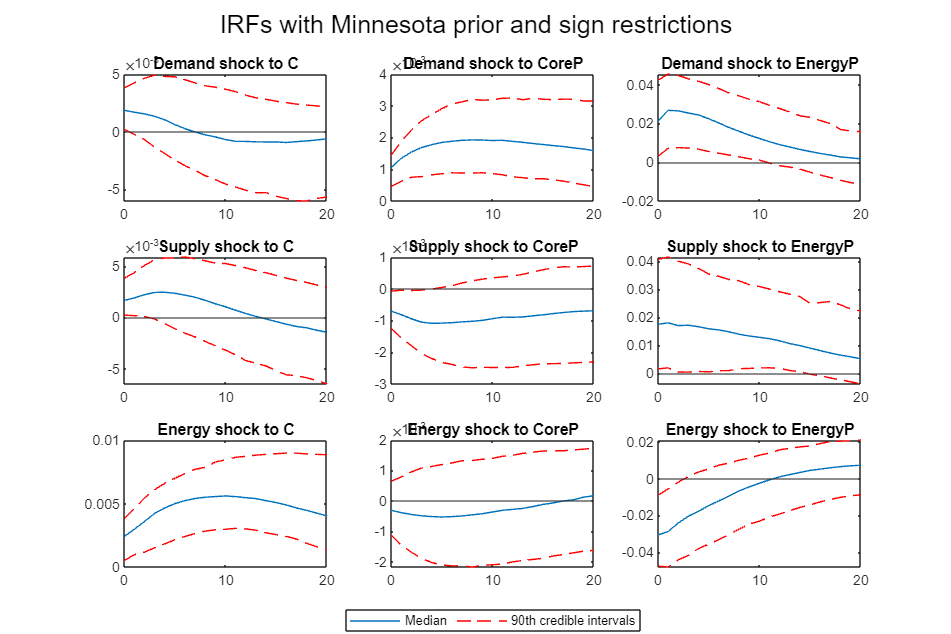

% Put VAR(4) in companion form and compute IRFs
minnesota.IRF = zeros(size(minnesota.index_sign, 2), set.n*set.n, set.irf_horizon+1);
for i=1:size(minnesota.index_sign, 2)
    % Reshape the parameter at every iteration
    B_post_draw = reshape(minnesota.b_post_sign(i,:,:), [], set.n);
    Gamma_draw = squeeze(minnesota.Gamma_sign(i, :, :));
    % Put B in companion form, select the betas without the intercept
    B_post_draw = [B_post_draw(2:end, :)'; eye(set.n*(set.p-1)) ...
        zeros(set.n*(set.p-1), set.n)];
    Gamma_draw = [Gamma_draw zeros(set.n, set.n*(set.p-1)); ...
        zeros(set.n*(set.p-1), set.n) zeros(set.n*(set.p-1), set.n*(set.p-1))];
    % Let's generate the IRFs for the selected horizon
    for h=0:set.irf_horizon
        %Use the companion form to generate the shocks
        shocks = (B_post_draw^h)*Gamma_draw; 
        shocks = shocks(1:set.n, 1:set.n);
        %shock1: 1:set.n, shock2: set.n+1:2*set.n, ...
        minnesota.IRF(i, :, h+1) = shocks(:); 
    end
end

clear b_location S_location B_post_draw Gamma_draw i shocks h

%Plot IRFs
figure('Position',[200 100 900 600]);
j=1;
for i=1:(set.n*set.n)
    subplot(set.n, set.n, i);
    plot(0:set.irf_horizon, prctile(squeeze(minnesota.IRF(:, i, :)), 50)', ...
        0:set.irf_horizon, prctile(squeeze(minnesota.IRF(:, i, :)), 5)', "--r", ...
        0:set.irf_horizon, prctile(squeeze(minnesota.IRF(:, i, :)), 95)', "--r");
    yline(0);
    title(sprintf("%s to %s", set.shock_names{j}, set.variable_names{i - set.n*(j-1)}))
    if rem(i, set.n) == 0; j = j+1; end
end
leg = legend("Median", "90th credible intervals", 'Location',...
    'southoutside','orientation','horizontal');
leg.Position(1) = 0.4;
leg.Position(2) = 0.01;
sgtitle("IRFs with Minnesota prior and sign restrictions")

#### 6) Reconstruct the remaining part of the sample using only the selected shock

For this last section we use the median of the posterior distrubutions under minnesota prior. We decompose the latest part of the sample not used for the estimation in 2 components (we define the median with the tilde):

- Expected: $y_{expected} = X \tilde{b}_{post}$

- Counterfactual with one shock: $y_{fake} = X \tilde{b}_{post} + \tilde{\Gamma}_{post} \; \epsilon_{fake}$

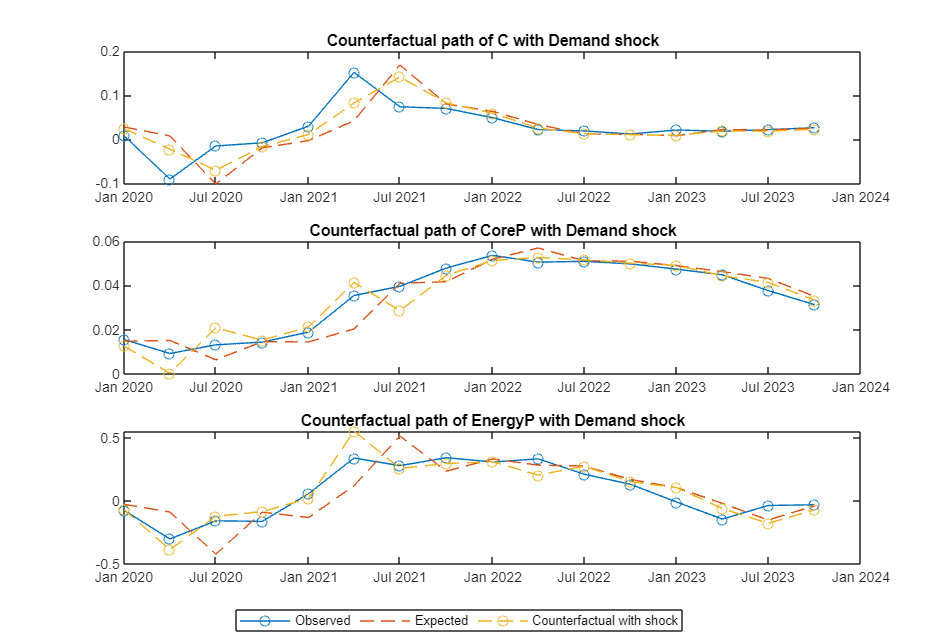

% Select the correct sample
x = set.x(set.T+1-set.p-set.growth_rate:end, :);
y = set.y(set.T+1-set.p-set.growth_rate:end, :);
X = kron(eye(set.n), set.x);
Y = set.y(:);

% Pre-allocate variables
counterfactual.eps = zeros(size(minnesota.index_sign,2), size(y,1), set.n);
counterfactual.eps_fake = zeros(size(minnesota.index_sign,2), size(y,1), set.n);
counterfactual.y_fake = zeros(size(minnesota.index_sign,2), size(y,1), set.n);
counterfactual.y_fake_perc = ...
    zeros(size(minnesota.index_sign,2), size(y,1)-set.growth_rate, set.n);
counterfactual.y_expected = zeros(size(minnesota.index_sign,2), size(y,1), set.n);
counterfactual.y_expected_perc = ...
    zeros(size(minnesota.index_sign,2), size(y,1)-set.growth_rate, set.n);

% Compute the structural shock, and construct the counterfactual path with
% only the selected shock
for i=1:size(minnesota.index_sign,2)
    b = reshape(squeeze(minnesota.b_post_sign(i,:,:)), [], set.n);
    Gamma = squeeze(minnesota.Gamma_sign(i,:,:));
    counterfactual.eps(i, :, :) = (inv(Gamma)*(y - x*b)')';
    %Construct the fake eps with only the selected shock
    counterfactual.eps_fake(i, :, set.select_shock) = ...
        counterfactual.eps(i, :, set.select_shock); 
    counterfactual.y_fake(i, :, :) = ...
        x*b + (Gamma*squeeze(counterfactual.eps_fake(i, :, :))')';
    counterfactual.y_fake_perc(i, :, :) = ...
        squeeze(counterfactual.y_fake(i, set.growth_rate+1:end, :)) ...
        - squeeze(counterfactual.y_fake(i, 1:end-set.growth_rate, :));
    counterfactual.y_expected(i, :, :) = x*b;
    counterfactual.y_expected_perc(i, :, :) = ...
        squeeze(counterfactual.y_expected(i, set.growth_rate+1:end, :)) ...
        - squeeze(counterfactual.y_expected(i, 1:end-set.growth_rate, :));
end

% Compute the annual change
y_obs_perc = y(set.growth_rate+1:end,:) - y(1:end-set.growth_rate,:);
y_fake_perc = squeeze(median(counterfactual.y_fake_perc(:, :, :)));
y_expected_perc = squeeze(median(counterfactual.y_expected_perc(:, :, :)));

% Plot the observed, expected and counterfactual path
figure('Position',[200 100 900 600]);
for i=1:set.n
    subplot(set.n, 1, i);
    plot(set.dates(set.T+1:end, :), y_obs_perc(:, i), "-o", ...
        set.dates(set.T+1:end, :), y_expected_perc(:, i), "--", ...
        set.dates(set.T+1:end, :), y_fake_perc(:, i), "--o")
    title(sprintf("Counterfactual path of %s with %s", ...
        set.variable_names{i}, set.shock_names{set.select_shock}))
end
leg = legend("Observed", "Expected", "Counterfactual with shock", ...
    'Location','southoutside','orientation','horizontal');
leg.Position(1) = 0.3;
leg.Position(2) = 0.01;

The middle panel shows that the counterfactual path of core prices with demand shock matches quite well the observed series, so it confirms that the the demand shock was the main driver of the recent surge in core inflation. If you run again the code by setting "set.select_shock = 2", you can check the same chart for supply shock. Instead, it confirms that the main driver in energy prices fluctuations was the supply shock.